% (x^2+sin(y))*dx+(1+x*cos(y))*dy=0

clear
% 1)
% y'=-(x^2+sin(y))/(1+x*cos(y))
syms x y(x) C
eqn=diff(y(x))==-(x^2+sin(y))/(1+x*cos(y))

$$eqn(x) = \frac{\partial }{\partial x}y\left(x\right)=-\frac{\sin\left(y\left(x\right)\right)+x^{2}}{x\,\cos\left(y\left(x\right)\right)+1}$$

ySol=dsolve(eqn)

$$ySol = \mathrm{solve}\left(\frac{x^{3}}{3}+\sin\left(y\right)\,x+C_{13}+y,y\right)$$

% solve(y + x*sin(y) == - x^3/3 - C12, y)
eq1= y + x*sin(y) + x^3/3 == C

$$eq1(x) = y\left(x\right)+x\,\sin\left(y\left(x\right)\right)+\frac{x^{3}}{3}=C$$


% 2)
syms x y
P(x,y)=x^2+sin(y)

$$P(x, y) = x^{2}+\sin\left(y\right)$$

Q(x,y)=1+x*cos(y)

$$Q(x, y) = x\,\cos\left(y\right)+1$$

chk1=diff(P,y)-diff(Q,x)

$$chk1(x, y) = 0$$

% dPy==dQx

% U(x,y)
% dUx=P, dUy=Q
syms C(y)
U=int(P(x,y),x)+C(y)

$$U = \frac{x^{3}}{3}+\sin\left(y\right)\,x+C\left(y\right)$$

% x^3/3 + sin(y)*x + C(y)
dUy=diff(U,y)

$$dUy = \frac{\partial }{\partial y}C\left(y\right)+x\,\cos\left(y\right)$$

% diff(C(y), y) + x*cos(y)
dCy=simplify(dUy-Q)

$$dCy(x, y) = \frac{\partial }{\partial y}C\left(y\right)-1$$

% diff(C(y), y) - 1
% C(y)=y+C1
% x^3/3 + sin(y)*x + y = C2

% 3)
x0=0;y0=0;
U=simplify(int(P(x,y),x,x0,x)+int(subs(Q(x,y),x,x0),y,y0,y))

$$U = \frac{x^{3}}{3}+\sin\left(y\right)\,x+y$$

syms C
eq2=U==C

$$eq2 = \frac{x^{3}}{3}+\sin\left(y\right)\,x+y=C$$

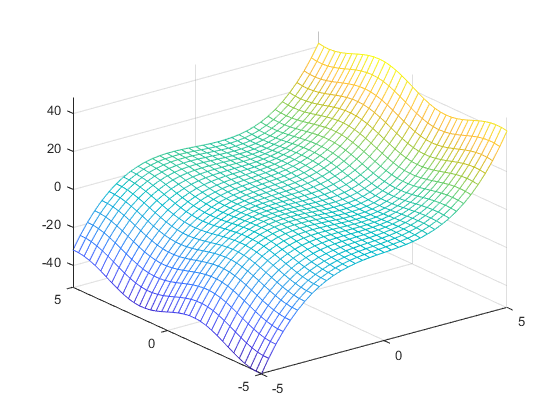

fmesh(U)